# Super Resolution Workflow

## Add Files

addpath 'Common Functions'
addpath 'Models'
addpath 'SuperResolution'

## Load Files

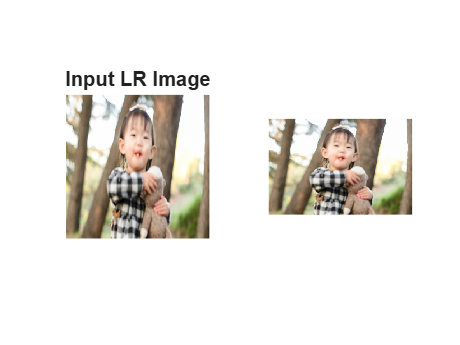

Image_name = 'child.jpeg';
image = imread(Image_name);
imshow(image);

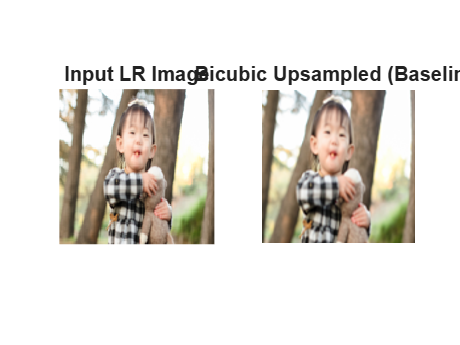

factor = 4;
img_LR  = imresize(image, [128 128]);
img_HR_size = size(img_LR, 1) * factor;
% Bicubic baseline for visual comparison
img_LR_up = imresize(img_LR, [img_HR_size img_HR_size], 'bicubic');

% Display
figure;
subplot(1,2,1); imshow(img_LR);    title('Input LR Image');
subplot(1,2,2); imshow(img_LR_up); title('Bicubic Upsampled (Baseline)');

## Define CNN and Noise Tensor

% Initial Network Parameters
input_depth  = 3;
num_channels = 64;
num_classes  = 3;
kernel_size  = 3;
imgSize = [img_HR_size, img_HR_size, input_depth];
%--- Define CNN ---
net = InpaintUnet3(imgSize, num_classes);
% Count parameters
totalParams = 0;
lrnables = net.Learnables;
for i = 1:height(lrnables)
    totalParams = totalParams + numel(extractdata(lrnables.Value{i}));
end
fprintf('Number of params: %d\n', totalParams);

Number of params: 1023203


% --- Noise Tensor ---
net_input       = get_noise(input_depth, 'noise', img_HR_size);
net_input_saved = dlarray(single(net_input), 'SSCB');

% Prepare LR image
img_LR_nom = im2double(img_LR);
img_LR_dl  = dlarray(single(img_LR_nom), 'SSCB');

## Loss and Gradient Function

function loss = computeSRLoss(out_HR, img_LR_dl, factor, lambda_tv)
    % Downsample HR output to LR size via average pooling
    out_LR = avgpool(out_HR, [factor factor], 'Stride', [factor factor], 'Padding', 'same');
    mse_loss = mean((out_LR - img_LR_dl).^2, 'all');

    %Total Variation: penalise spatial gradients in output  
    dx = out_HR(:, 2:end, :, :) - out_HR(:, 1:end-1, :, :);
    dy = out_HR(2:end, :, :, :) - out_HR(1:end-1, :, :, :);
    tv_loss = mean(abs(dx), 'all') + mean(abs(dy), 'all');

    loss = mse_loss + lambda_tv * tv_loss;
end

function [loss, gradients, out_HR, out_avg] = modelGradientsSR( ...
        net, net_input_saved, img_LR_dl, out_avg, exp_weight, reg_noise_std, factor)

   
    if reg_noise_std > 0
        noise = dlarray(randn(size(extractdata(net_input_saved)), 'single'), 'SSCB');
        net_input = net_input_saved + noise * reg_noise_std;
    else
        net_input = net_input_saved;
    end

    % Forward pass -> HR output
    out_HR = forward(net, net_input);

    % Loss: consistency with LR observation + TV smoothness on HR
    loss = computeSRLoss(out_HR, img_LR_dl, factor, 1e-4);

    % Exponential moving average of outputs (smoothed result)
    out_detached = dlarray(extractdata(out_HR), 'SSCB');
    if isempty(out_avg)
        out_avg = out_detached;
    else
        out_avg = out_avg * exp_weight + out_detached * (1 - exp_weight);
    end

    gradients = dlgradient(loss, net.Learnables);
end

## Optimization Steps

if factor == 4
    num_iter      = 2000;
    reg_noise_std = 0.03;
elseif factor == 8
    num_iter      = 4000;
    reg_noise_std = 0.05;
else
    error('Only upscaling factors 4 or 8 are supported.');
end

LR = 0.01;
exp_weight = 0.99;
show_every = 10;
PLOT  = 1;
out_avg = [];
trailingAvg = [];
trailingAvgSq = [];
psnr_LR_last = -inf;
last_learnables = [];

% --- Training Loop ---
for iter = 1:num_iter

    [loss, gradients, out_HR, out_avg] = dlfeval(@modelGradientsSR, ...
        net, net_input_saved, img_LR_dl, out_avg, exp_weight, reg_noise_std, factor);

    [net, trailingAvg, trailingAvgSq] = adamupdate(net, gradients, ...
        trailingAvg, trailingAvgSq, iter, LR);

    % --- Convert dlarray to numeric ---
    out_HR_num  = double(gather(extractdata(out_HR)));
    out_HR_num  = out_HR_num(:,:,:,1);
    out_avg_num = double(gather(extractdata(out_avg)));
    out_avg_num = out_avg_num(:,:,:,1);

    % Downsample HR output back to LR size for PSNR vs LR input
    out_LR_num = imresize(out_HR_num, 1/factor);
    psnr_LR    = psnr(out_LR_num, img_LR_nom);

    fprintf('Iter %05d  Loss %.6f  PSNR_LR: %.4f\r', ...
        iter, gather(extractdata(loss)), psnr_LR);

    % --- Start Plotting ---
    if PLOT && mod(iter, show_every) == 0
        out_plt     = min(max(out_HR_num,  0), 1);
        out_avg_plt = min(max(out_avg_num, 0), 1);

        fig = figure(1); clf;
        set(fig, 'Visible', 'on');

        subplot(1,3,1);
        imshow(im2double(img_LR_up)); axis image off;
        title('Bicubic Baseline');

        subplot(1,3,2);
        imshow(out_plt); axis image off;
        title(sprintf('DIP SR Output (Iter %d | PSNR\\_LR %.2f dB)', iter, psnr_LR));

        subplot(1,3,3);
        imshow(out_avg_plt); axis image off;
        title('Smoothed SR Output (EMA)');

        drawnow;
    end

    % --- Back Tracking Logic ---
    if mod(iter, show_every) ~= 0
        if psnr_LR - psnr_LR_last < -5
            fprintf('\nPSNR drop detected — restoring previous checkpoint.\n');
            net.Learnables.Value = last_learnables;
            break;
        else
            last_learnables = net.Learnables.Value;
            psnr_LR_last    = psnr_LR;
        end
    end

end

Iter 00001  Loss 0.102470  PSNR_LR: 9.8462
Iter 00002  Loss 0.090121  PSNR_LR: 10.4331
Iter 00003  Loss 0.078843  PSNR_LR: 11.0210
Iter 00004  Loss 0.072714  PSNR_LR: 11.3755
Iter 00005  Loss 0.070916  PSNR_LR: 11.4878
Iter 00006  Loss 0.065318  PSNR_LR: 11.8455
Iter 00007  Loss 0.064179  PSNR_LR: 11.9228
Iter 00008  Loss 0.063139  PSNR_LR: 11.9944
Iter 00009  Loss 0.064906  PSNR_LR: 11.8744
Iter 00010  Loss 0.062100  PSNR_LR: 12.0666
Iter 00011  Loss 0.063178  PSNR_LR: 11.9919
Iter 00012  Loss 0.064251  PSNR_LR: 11.9187
Iter 00013  Loss 0.063664  PSNR_LR: 11.9586
Iter 00014  Loss 0.063245  PSNR_LR: 11.9879
Iter 00015  Loss 0.062395  PSNR_LR: 12.0471
Iter 00016  Loss 0.062978  PSNR_LR: 12.0069
Iter 00017  Loss 0.062382  PSNR_LR: 12.0483
Iter 00018  Loss 0.061633  PSNR_LR: 12.1007
Iter 00019  Loss 0.063515  PSNR_LR: 11.9696
Iter 00020  Loss 0.063216  PSNR_LR: 11.9901
Iter 00021  Loss 0.065524  PSNR_LR: 11.8342
Iter 00022  Loss 0.062939  PSNR_LR: 12.0092
Iter 00023  Loss 0.063261  PSNR_L


% Save Final SR Output
out_HR_final  = forward(net, net_input_saved);
out_HR_final_num = double(gather(extractdata(out_HR_final)));
out_HR_final_num = min(max(out_HR_final_num(:,:,:,1), 0), 1);

out_avg_final = double(gather(extractdata(out_avg)));
out_avg_final = min(max(out_avg_final(:,:,:,1), 0), 1);

% Display final comparison
figure;
subplot(1,3,1); imshow(im2double(img_LR));title('Input LR Image');
subplot(1,3,2); imshow(im2double(img_LR_up));title('Bicubic Baseline');
subplot(1,3,3); imshow(out_avg_final);title('DIP Super Resolution (Smoothed)');

% Save outputs to disk
imwrite(out_HR_final_num,'SR_output_raw.png');
imwrite(out_avg_final,'SR_output_smoothed.png');
fprintf('\nDone. Outputs saved to SR_output_raw.png and SR_output_smoothed.png\n');